### 初始化

clc;
clear

### 参数设置

M = 100000;         % Sample Points
Fs = 10E6;          % Sample Rate
pathname = 'C:\Users\Labuser\Desktop\InstrumentStudio\Data\Instrument_Capture_06_Multiplier (7) Oscilloscope - Waveform Data.csv';


### 数据读取

range_index_head = ['A' num2str(11)];
range_index_tail = ['B' num2str(10+M)];
range_index = [range_index_head ':' range_index_tail];
wave_data = readmatrix(pathname,"Range",range_index);
vout = wave_data(:,1) - wave_data(:,2);

### 计算THD

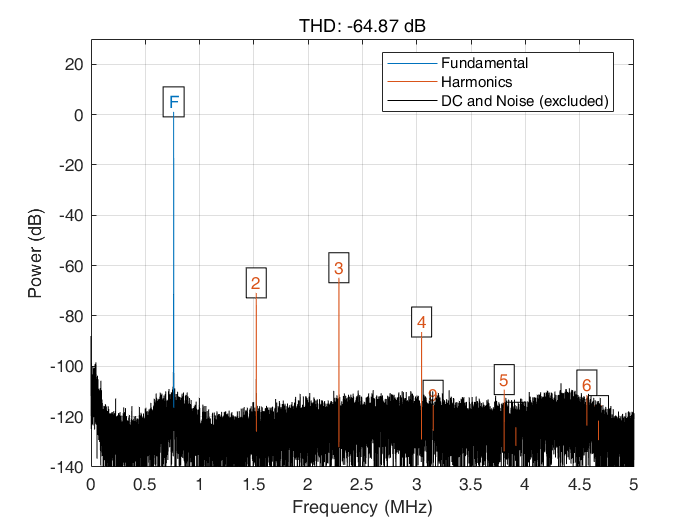

ans = -64.8671

figure
thd(vout, Fs, 9, 'aliased')

### Export results

[r, harmpow, harmfreq] = thd(vout, Fs, 7, 'aliased');

函数或变量 'vout' 无法识别。

channel = 5
Time = datetime('now', 'InputFormat','dd-MMM-uuuu HH:mm:ss');
THD = r;
HD = harmpow(1:4);          % record THD and base, HD1, HD2, HD3;
fid = fopen('results.csv', 'a+')
fprintf(fid, "%s, %s, %d, %d, %d, %.2f, %.2f, %.2f, %.2f, %.2f\n", ...
    Time, pathname, channel,Fs/1E6,M,THD, HD);
fclose(fid);